# 学習・テストデータの簡易調査

Copyright 2020 Michio Inoue

まずはファイル数、音声の長さなど確認しておきます。

## まとめ

- 学習用データ数：426 ファイル, テスト用データ 107 ファイル

- ファイル数は作曲家ごとにばらつきあり（最小 8ファイル、最大 45 ファイル）

- １ファイルあたりの曲の長さもバラツキ大きい。

- 学習用データでは短いものは 22 秒 から 長いものは 70分 まで

- テスト用データでは短いものが 54 秒、長いものが 45 分以上

- サンプルレートは 44.1 kHz だが、学習用データに １ファイルだけ 22.05 kHz（494.mp3）

- ビットレートは 64 がメインで 128 もアリ。１曲だけ 40 がみられた（494.mp3）

- 曲番号・作曲家名については trainDataSummary.mat に保存

### 使用したツール

- MATLAB R2020b

- Audio Toolbox

- Signal Processing Toolbox

- Machine Learning and Statistics Toolbox

## 事前準備

ディレクトリ情報の確保

settings = jsondecode(fileread('..\settings.json'));
datadir = settings.RAW_DATA_DIR
outputdir = settings.PROCESSED_DATA_DIR

## 学習データの作曲家別ファイル数

'train.csv' を読み込みます。

filepath = fullfile(datadir,'train.csv');
traindata = readtable(filepath);

冒頭だけ見ると

head(traindata)

ans = 8×4 table
     filename          artist         artist_id                        title                     
    ___________    _______________    _________    ______________________________________________

    {'315.mp3'}    {'rachmaninov'}       10        {'パガニーニの主題による狂詩曲, Op. 43'           }
    {'465.mp3'}    {'beethoven'  }        7        {'ヴァイオリンソナタ第1番ニ長調, Op. 12-1 第1楽章' }
    {'399.mp3'}    {'chopin'     }        9        {'4つのマズルカ Op. 17 第4番'                   }
    {'244.mp3'}    {'mendelssohn'}        3        {'夏の夜の夢 間奏曲'                            }
    {'405.mp3'}    {'mendelssohn'}        3        {'夏の夜の夢 フィナーレ'                        }
    {'324.mp3'}    {'mendelssohn'}        3        {'交響曲第3番イ短調 スコットランド, Op. 56 第4楽章'}
    {'152.mp3'}    {'chopin'     }        9        {'4つのマズルカ Op. 68 第1番'                   }
    {'125.mp3'}    {'wagner'     }       14        {'ファウスト序曲'                              }


合計ファイル数

height(traindata) 

ans = 426

作曲家別ファイル数

tabulate(traindata.artist) 

        Value    Count   Percent
  rachmaninov       24      5.63%
    beethoven       29      6.81%
       chopin       46     10.80%
  mendelssohn       18      4.23%
       wagner       14      3.29%
     schumann       36      8.45%
  tchaikovsky       28      6.57%
       handel       29      6.81%
         bach       38      8.92%
      debussy       30      7.04%
        verdi       28      6.57%
       bartok       25      5.87%
       brahms       40      9.39%
       mozart       33      7.75%
        grieg        8      1.88%


mendelssohn ([フェリックス・メンデルスゾーン](https://ja.wikipedia.org/wiki/%E3%83%95%E3%82%A7%E3%83%AA%E3%83%83%E3%82%AF%E3%82%B9%E3%83%BB%E3%83%A1%E3%83%B3%E3%83%87%E3%83%AB%E3%82%B9%E3%82%BE%E3%83%BC%E3%83%B3)), wagner ([リヒャルト・ワーグナー](https://ja.wikipedia.org/wiki/%E3%83%AA%E3%83%92%E3%83%A3%E3%83%AB%E3%83%88%E3%83%BB%E3%83%AF%E3%83%BC%E3%82%B0%E3%83%8A%E3%83%BC)), greig ([エドヴァルド・グリーグ:](https://ja.wikipedia.org/wiki/%E3%82%A8%E3%83%89%E3%83%B4%E3%82%A1%E3%83%AB%E3%83%89%E3%83%BB%E3%82%B0%E3%83%AA%E3%83%BC%E3%82%B0)) の楽曲が少な目なのが気になりますが、とはいえそこまで大きな差ではない。

## 各ファイルのデータ長さ

試しに 0.mp3 を見ると、

filepath = fullfile(datadir,'train','0.mp3');
info = audioinfo(filepath)

info = フィールドをもつ struct :
             Filename: 'C:\Users\minoue\OneDrive - MathWorks\Desktop\competition\toshare\classifyClassicMusicComposer\data\train\0.mp3'
    CompressionMethod: 'MP3'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 21598846
             Duration: 489.7697
                Title: []
              Comment: []
               Artist: []
              BitRate: 64


全ファイルで SampleRate, TotalSamples, Duration, BitRate を確認してみます。

filepath = fullfile(datadir,'train'); % train フォルダへのパス
ads = audioDatastore(filepath); % フォルダ内のファイル確認

Ntotal = length(ads.Files); % train 内の総ファイル数

trainInfo = table(); % 情報集約用変数
for ii=1:Ntotal
    eachfile = ads.Files{ii}; % ファイル名
    info = audioinfo(eachfile);
    
    sampleRate = info.SampleRate;
    duration = info.Duration;
    bitRate = info.BitRate;
    
    tmp = table(sampleRate, duration, bitRate); % table 型にまとめて
    trainInfo = [trainInfo; tmp]; %#ok<AGROW> % 追記
end
[~,filenames,~] = fileparts(ads.Files);
trainInfo.filename = string(filenames) + ".mp3"; % 名前には拡張子加えておく

冒頭だけ確認

head(trainInfo)

ans = 8×4 table
    sampleRate    duration    bitRate    filename 
    __________    ________    _______    _________

      44100        489.77        64      "0.mp3"  
      44100        164.68        64      "1.mp3"  
      44100        131.42       128      "10.mp3" 
      44100        952.16        64      "100.mp3"
      44100        3312.7        64      "104.mp3"
      44100        144.88        64      "105.mp3"
      44100        425.38        64      "106.mp3"
      44100        102.16        64      "108.mp3"


train.csv からの作曲家名情報とマージして保存（`trainDataSummary.mat`）

traindata.filename = string(traindata.filename); % filename は string 型で統一したうえで join
traindata = join(traindata,trainInfo,"Keys","filename");
head(traindata)

ans = 8×7 table
    filename         artist         artist_id                        title                         sampleRate    duration    bitRate
    _________    _______________    _________    ______________________________________________    __________    ________    _______

    "315.mp3"    {'rachmaninov'}       10        {'パガニーニの主題による狂詩曲, Op. 43'           }      44100          1329        64  
    "465.mp3"    {'beethoven'  }        7        {'ヴァイオリンソナタ第1番ニ長調, Op. 12-1 第1楽章' }      44100        373.13        64  
    "399.mp3"    {'chopin'     }        9        {'4つのマズルカ Op. 17 第4番'                   }      44100        251.45        64  
    "244.mp3"    {'mendelssohn'}        3        {'夏の夜の夢 間奏曲'                            }      44100        222.62       128  
    "405.mp3"    {'mendelssohn'}        3        {'夏の夜の夢 フィナーレ'                        }      44100        264.46       128  
    "324.mp3"    {'mendelssohn'}        3        {'交響曲第3番イ短調 スコットランド, Op. 56 第4楽章'}      

データは後で使用するので保存しておきます

filename = fullfile(outputdir,'trainDataSummary.mat');
save(filename,'traindata')

曲の長さを見るとほとんどが10分以内だが、、えらい長いものがありますね。

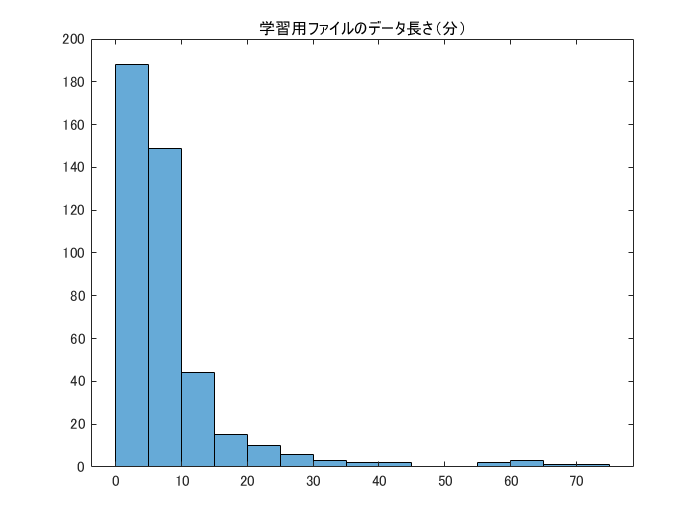

histogram(trainInfo.duration/60)
title('学習用ファイルのデータ長さ（分）')

データの長さを作曲家別にまとめると・・短いものは 22 秒 から 長いものは 4300 秒まで様々ですが、、wagner は長いな・・。

groupsummary(traindata,'artist',{'sum','min','median','max'},'duration')

ans = 15×6 table
        artist         GroupCount    sum_duration    min_duration    median_duration    max_duration
    _______________    __________    ____________    ____________    _______________    ____________

    {'bach'       }        38           5625.1          22.779           88.163            510.51   
    {'bartok'     }        25            11034           161.1           425.38            890.54   
    {'beethoven'  }        29            11456          124.94           362.14            1229.2   
    {'brahms'     }        40            19990          69.721           457.99            1236.6   
    {'chopin'     }        46             7405          21.447            140.3            360.02   
    {'debussy'    }        30           5860.3          127.06           166.58            494.97   
    {'grieg'      }         8           2571.6          139.55           244.62            982.39   
    {'handel'     }        29            13804          45.767           

sampleRate の最大値、最小値を確認すると・・

groupsummary(traindata,'artist',{'min','max'},'sampleRate')

ans = 15×4 table
        artist         GroupCount    min_sampleRate    max_sampleRate
    _______________    __________    ______________    ______________

    {'bach'       }        38            44100             44100     
    {'bartok'     }        25            44100             44100     
    {'beethoven'  }        29            44100             44100     
    {'brahms'     }        40            44100             44100     
    {'chopin'     }        46            44100             44100     
    {'debussy'    }        30            22050             44100     
    {'grieg'      }         8            44100             44100     
    {'handel'     }        29            44100             44100     
    {'mendelssohn'}        18            44100             44100     
    {'mozart'     }        33            44100             44100     
    {'rachmaninov'}        24            44100             44100     
    {'schumann'   }        36            44100             44100     
  

'debussy' だけ 22.05 kHz のものがある。

traindata(traindata.sampleRate == 22050,:)

ans = 1×7 table
    filename       artist       artist_id        title        sampleRate    duration    bitRate
    _________    ___________    _________    _____________    __________    ________    _______

    "494.mp3"    {'debussy'}        1        {'シランクス'}      22050        153.1        40   


この 494.mp3 だけです。bitRate も 40 とレアキャラ。全体見ると bitRate はは 64 がほとんど、128 がちょこちょこ存在。

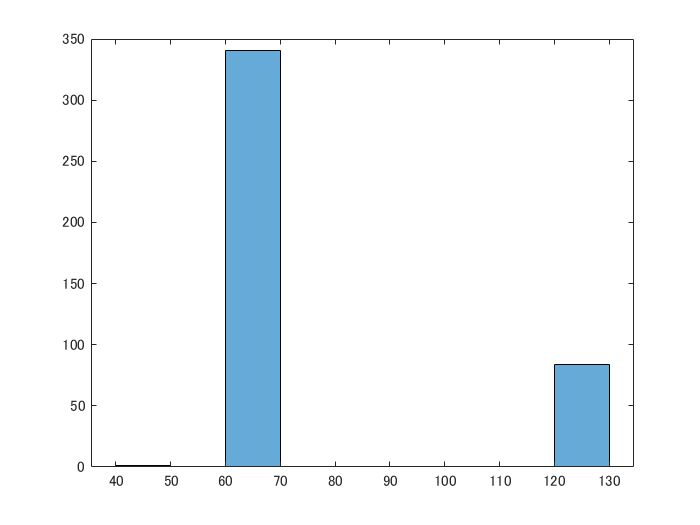

histogram(traindata.bitRate)

## テスト用データ

同様に全ファイルで SampleRate, TotalSamples, Duration, BitRate を確認してみます。

filepath = fullfile(datadir,'test'); % test フォルダへのパス
ads = audioDatastore(filepath); % フォルダ内のファイル確認

Ntotal = length(ads.Files); % test 内の総ファイル数

testInfo = table(); % 情報集約用変数
for ii=1:Ntotal
    eachfile = ads.Files{ii}; % ファイルへのパス
    info = audioinfo(eachfile); % 情報読み込み
    
    sampleRate = info.SampleRate;
    duration = info.Duration;
    bitRate = info.BitRate;
    
    tmp = table(sampleRate, duration, bitRate);
    testInfo = [testInfo; tmp]; %#ok<AGROW> 
end
[~,filenames,~] = fileparts(ads.Files);
testInfo.filename = string(filenames) + ".mp3"; % 拡張子加えておく

冒頭だけ確認

head(testInfo)

ans = 8×4 table
    sampleRate    duration    bitRate    filename 
    __________    ________    _______    _________

      44100         97.28       64       "101.mp3"
      44100        410.85       64       "102.mp3"
      44100        148.61       64       "103.mp3"
      44100        267.18       64       "107.mp3"
      44100        131.24       64       "110.mp3"
      44100        166.09       64       "112.mp3"
      44100         463.6       64       "113.mp3"
      44100        328.96       64       "117.mp3"


データの長さをヒストグラムで。

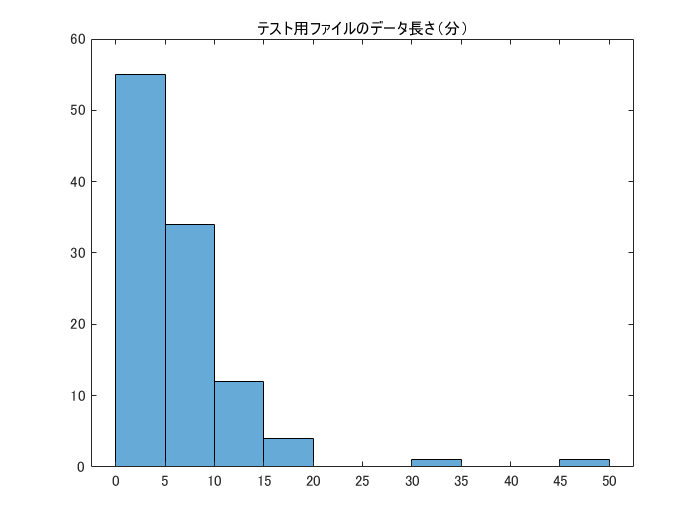

histogram(testInfo.duration/60)
title('テスト用ファイルのデータ長さ（分）')

データ長は短いものが 54 秒、長いものが 45 分以上。サンプルレートは 44.1 kHz のみですね。

summary(testInfo)

Variables:

    sampleRate: 107×1 double

        Values:

            Min        44100  
            Median     44100  
            Max        44100  

    duration: 107×1 double

        Values:

            Min        54.491 
            Median     287.16 
            Max        2731.3 

    bitRate: 107×1 double

        Values:

            Min          64   
            Median       64   
            Max         128   

    filename: 107×1 string



## 余談

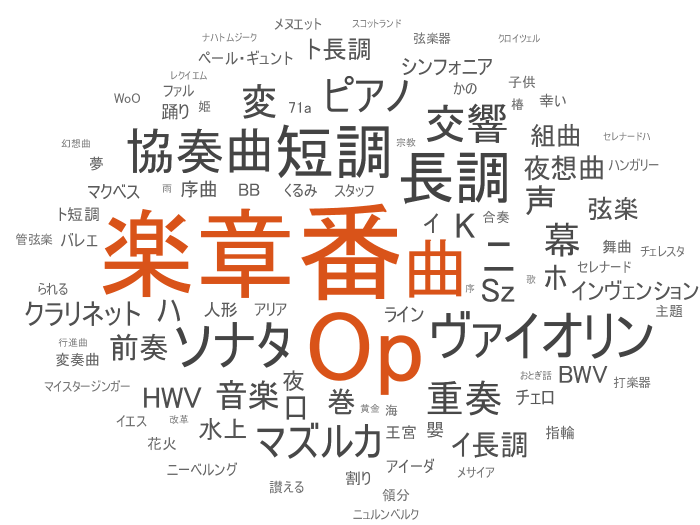

wordcloud(traindata.title)